% Load data, and display in time axis
fs.avg = 500;
fs.min = 450; 
fs.max = 550;

acc = imu(:, 2:4);
gyr = imu(:, 5:7);


% data = acc(:,2);
% figure;
% plot(data);
% hold on;
% filtered_ax = smoothdata(data,'movmean', 5);
% plot(filtered_ax);
% title('acc avg 5');
% xlabel('idx');
% ylabel('ax(m/s^2)');
% grid on;



% % tiledlayout(7,1); nexttile;
% figure;
% plot(acc(:,1));
% hold on;
% plot(gyr(:, 1));
% title('timestamp');
% xlabel('index');
% ylabel('ts(ns)');
% grid on;
% 
% % ts_rebase = (data(:,1) - data(1,1))*1e-9;
% acc_ts_rebase = (acc(:,1) - acc(1,1))*1e-9;
% gyr_ts_rebase = (gyr(:,1) - gyr(1,1))*1e-9;
% delay = 30; %ms
% avg_window_t = 2*delay*0.001; 
% 
% figure;
% plot(acc_ts_rebase, acc(:,2));
% hold on;
% filtered_ax = smoothdata(data,'movmean', avg_window_t*fs);
% plot(acc_ts_rebase, filtered_ax);
% title('acc_x');
% xlabel('time(s)');
% ylabel('ax(m/s^2)');
% grid on;
% 
% figure;
% plot(acc_ts_rebase, acc(:,3));
% hold on;
% filtered_ay = smoothdata(acc(:,3),'movmean', avg_window_t*fs);
% plot(acc_ts_rebase, filtered_ay);
% title('acc_y');
% xlabel('time(s)');
% ylabel('ay(m/s^2)');
% grid on;
% 
% figure;
% plot(acc_ts_rebase, acc(:,4));
% hold on;
% filtered_az = smoothdata(acc(:,4),'movmean', avg_window_t*fs);
% plot(acc_ts_rebase, filtered_az);
% title('acc_z');
% xlabel('time(s)');
% ylabel('az(m/s^2)');
% grid on;
% 
% figure;
% plot(gyr_ts_rebase, gyr(:,2));
% hold on;
% filtered_rx = smoothdata(gyr(:,2),'movmean', avg_window_t*fs);
% plot(gyr_ts_rebase, filtered_rx);
% title('gyr_x');
% xlabel('time(s)');
% ylabel('rx(rad/s)');
% grid on;
% 
% figure;
% plot(gyr_ts_rebase, gyr(:,3));
% hold on;
% filtered_ry = smoothdata(gyr(:,3),'movmean', avg_window_t*fs);
% plot(gyr_ts_rebase, filtered_ry);
% title('gyr_y');
% xlabel('time(s)');
% ylabel('ry(rad/s)');
% grid on;
% 
% figure;
% plot(gyr_ts_rebase, gyr(:,4));
% hold on;
% filtered_rz = smoothdata(gyr(:,4),'movmean', avg_window_t*fs);
% plot(gyr_ts_rebase, filtered_rz);
% title('gyr_z');
% xlabel('time(s)');
% ylabel('rz(rad/s)');
% grid on;


% select a "stable" data section based on time(s)
% format long;
% format longG;
% selected_time_range = [10, 900];
% index_begin = 1 + selected_time_range(1) * fs;
% index_end = 1 + selected_time_range(2) * fs;
% selected_data = data(index_begin:index_end, :);

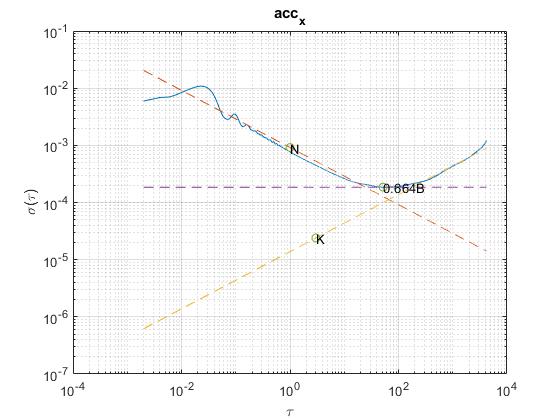

% allan variance calculation
% sensitive to data fluctuation, and data length as fluctuation's consequence
[velocity_random_walk_x, acc_random_walk_x] = allanVarAnalysis(acc(:,1),fs,'acc_x');

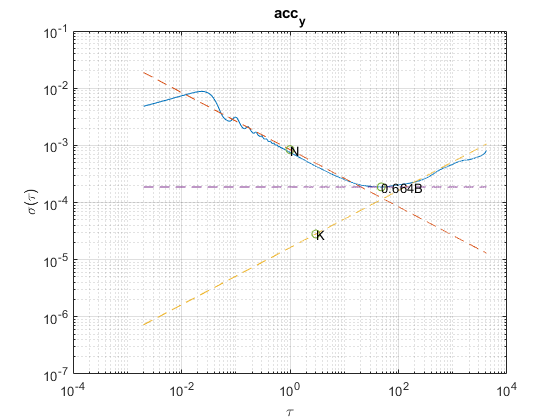

[velocity_random_walk_y, acc_random_walk_y] = allanVarAnalysis(acc(:,2),fs,'acc_y');

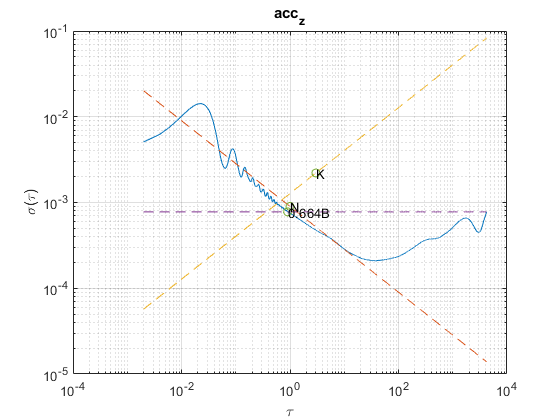

[velocity_random_walk_z, acc_random_walk_z] = allanVarAnalysis(acc(:,3),fs,'acc_z');

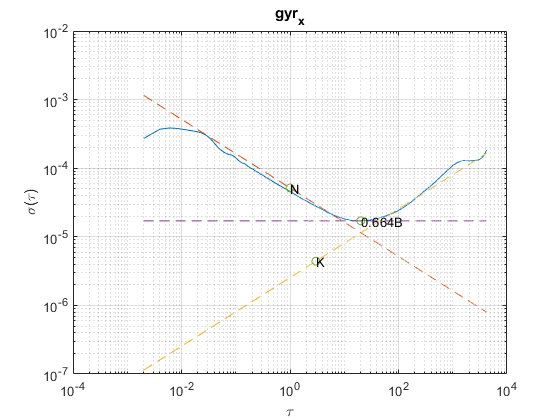

[angle_random_walk_x, rate_random_walk_x] = allanVarAnalysis(gyr(:,1),fs,'gyr_x');

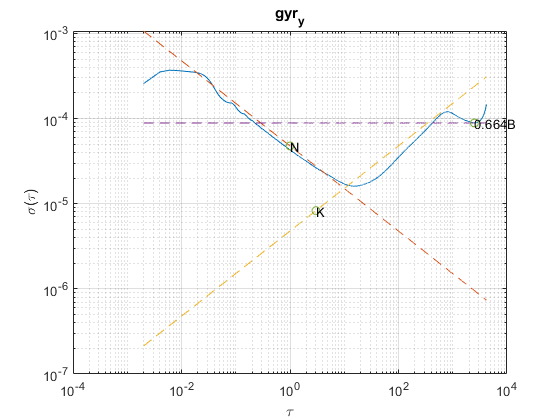

[angle_random_walk_y, rate_random_walk_y] = allanVarAnalysis(gyr(:,2),fs,'gyr_y');

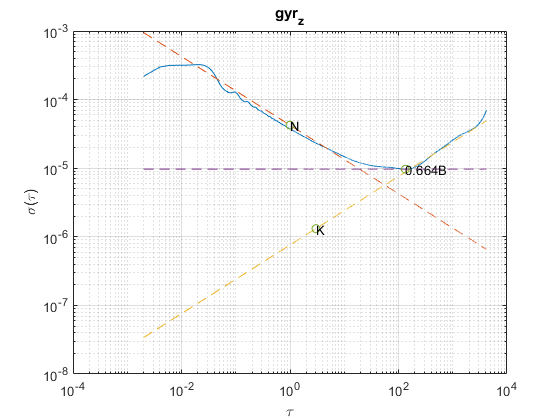

[angle_random_walk_z, rate_random_walk_z] = allanVarAnalysis(gyr(:,3),fs,'gyr_z');

bandwidth_factor = sqrt(fs.max/2);
deviation_ax_white_noise = velocity_random_walk_x * bandwidth_factor

deviation_ax_white_noise = 0.0152

deviation_ay_white_noise = velocity_random_walk_y * bandwidth_factor

deviation_ay_white_noise = 0.0140

deviation_az_white_noise = velocity_random_walk_z * bandwidth_factor

deviation_az_white_noise = 0.0149

average_acc_white_noise = (deviation_ax_white_noise + deviation_ay_white_noise + deviation_az_white_noise)/3

average_acc_white_noise = 0.0147

deviation_rx_white_noise = angle_random_walk_x * bandwidth_factor

deviation_rx_white_noise = 8.5519e-04

deviation_ry_white_noise = angle_random_walk_y * bandwidth_factor

deviation_ry_white_noise = 7.9078e-04

deviation_rz_white_noise = angle_random_walk_z * bandwidth_factor

deviation_rz_white_noise = 7.0364e-04

average_gyr_white_noise = (deviation_rx_white_noise + deviation_ry_white_noise + deviation_rz_white_noise)/3

average_gyr_white_noise = 7.8320e-04


deviation_ax_random_walk = acc_random_walk_x * bandwidth_factor

deviation_ax_random_walk = 3.9657e-04

deviation_ay_random_walk = acc_random_walk_y * bandwidth_factor

deviation_ay_random_walk = 4.6670e-04

deviation_az_random_walk = acc_random_walk_z * bandwidth_factor

deviation_az_random_walk = 0.0367

average_acc_random_walk = (deviation_ax_random_walk + deviation_ay_random_walk + deviation_az_random_walk)/3

average_acc_random_walk = 0.0125

deviation_rx_random_walk = rate_random_walk_x * bandwidth_factor

deviation_rx_random_walk = 7.3099e-05

deviation_ry_random_walk = rate_random_walk_y * bandwidth_factor

deviation_ry_random_walk = 1.3731e-04

deviation_rz_random_walk = rate_random_walk_z * bandwidth_factor

deviation_rz_random_walk = 2.1815e-05

average_gyr_random_walk = (deviation_rx_random_walk + deviation_ry_random_walk + deviation_rz_random_walk)/3

average_gyr_random_walk = 7.7410e-05

% % direct compute white noise
% direct_deviation_ax_white_noise = sqrt(var(selected_data(:,2)))
% direct_deviation_ay_white_noise = sqrt(var(selected_data(:,3)))
% direct_deviation_az_white_noise = sqrt(var(selected_data(:,4)))
% direct_deviation_rx_white_noise = sqrt(var(selected_data(:,5)))
% direct_deviation_ry_white_noise = sqrt(var(selected_data(:,6)))
% direct_deviation_rz_white_noise = sqrt(var(selected_data(:,7)))
% % random walk
% rw_window_t = 10
% rw_delta_ax = genRWdeltaSample(filtered_ax, fs, rw_window_t);
% rw_delta_ay = genRWdeltaSample(filtered_ay, fs, rw_window_t);
% rw_delta_az = genRWdeltaSample(filtered_az, fs, rw_window_t);
% rw_delta_rx = genRWdeltaSample(filtered_rx, fs, rw_window_t);
% rw_delta_ry = genRWdeltaSample(filtered_ry, fs, rw_window_t);
% rw_delta_rz = genRWdeltaSample(filtered_rz, fs, rw_window_t);
% 
% direct_deviation_ax_random_walk = sqrt(var(rw_delta_ax) / rw_window_t)
% direct_deviation_ay_random_walk = sqrt(var(rw_delta_ay) / rw_window_t)
% direct_deviation_az_random_walk = sqrt(var(rw_delta_az) / rw_window_t)
% direct_deviation_rx_random_walk = sqrt(var(rw_delta_rx) / rw_window_t)
% direct_deviation_ry_random_walk = sqrt(var(rw_delta_ry) / rw_window_t)
% direct_deviation_rz_random_walk = sqrt(var(rw_delta_rz) / rw_window_t)

% function sample = genRWdeltaSample(data, fs, delta_t)
%     safe_thred = 10;
%     sample_len = cast(size(data,1) - (safe_thred + delta_t)*fs, "uint32");
%     data_cut_end = data(1 : sample_len);
%     data_delta = data(cast(delta_t*fs, "uint32") : cast(delta_t*fs, "uint32") + sample_len - 1);
%     sample = data_cut_end - data_delta;
%     figure;
%     plot (sample);
%     xlabel('index');
%     ylabel('rw delta');
%     grid on;
% end



function [N,K] = allanVarAnalysis(data, fps, data_name)
%     t0 = 1/fps;
%     inte_data = cumsum(data, 1)*t0;
    maxNumM = 10000; % number of x axis points of allan variance plot 
%     L = size(inte_data, 1);
    L = size(data, 1);
    maxM = 2.^floor(log2(L/2)); 
    m = logspace(log10(1), log10(maxM), maxNumM).';
    m = ceil(m); % m must be an integer.
    m = unique(m); % Remove duplicates.

    [avar, tau] = allanvar(data, m, fps.avg);
    adev = sqrt(avar);
    
    % Find the index where the slope of the log-scaled Allan deviation is equal
    % to the slope specified.
    slope = -0.5;
    logtau = log10(tau);
    logadev = log10(adev);
    dlogadev = diff(logadev) ./ diff(logtau);
    [~, i] = min(abs(dlogadev - slope));
    
    % --------------Line fitting manual fix-----------------
%     if strcmp(data_name, 'gyr_y')
%         orig_deri_diff = abs(dlogadev - slope);
%         orig_deri_diff(i) = [];
%         [~, i] = min(orig_deri_diff);
%     end

    % Find the y-intercept of the line.
    b = logadev(i) - slope*logtau(i);

    % Determine the angle random walk coefficient from the line.
    logN = slope*log(1*fps.avg/fps.max) + b; %% use fs > fs_real for N
    N = 10^logN;
    
    % Plot the results.
    tauN = 1;
    lineN = N ./ sqrt(tau);
    
    % Find the index where the slope of the log-scaled Allan deviation is equal
    % to the slope specified.
    slope = 0.5;
    logtau = log10(tau);
    logadev = log10(adev);
    dlogadev = diff(logadev) ./ diff(logtau);
    [~, i] = min(abs(dlogadev - slope));
    
    % --------------Line fitting manual fix-----------------
%     orig_deri_diff = abs(dlogadev - slope);
%     orig_deri_diff(i) = [];
%     [~, i] = min(orig_deri_diff);

    % Find the y-intercept of the line.
    b = logadev(i) - slope*logtau(i);

    % Determine the rate random walk coefficient from the line.
    logK = slope*log10(3*fps.avg/fps.min) + b; %% use fs < fs_real for K
    K = 10^logK;
    
    % Plot the results.
    tauK = 3;
    lineK = K .* sqrt(tau/3);
    
    % Find the index where the slope of the log-scaled Allan deviation is equal
% to the slope specified.
    slope = 0;
    logtau = log10(tau);
    logadev = log10(adev);
    dlogadev = diff(logadev) ./ diff(logtau);
    [~, i] = min(abs(dlogadev - slope));
    
    % Find the y-intercept of the line.
    b = logadev(i) - slope*logtau(i);
    
    % Determine the bias instability coefficient from the line.
    scfB = sqrt(2*log(2)/pi);
    logB = b - log10(scfB);
    B = 10^logB;
    
    % Plot the results.
    tauB = tau(i);
    lineB = B * scfB * ones(size(tau));
    

    tauParams = [tauN, tauK, tauB];
    params = [N, K, scfB*B];
    figure
    loglog(tau, adev, tau, [lineN, lineK, lineB], '--', ...
        tauParams, params, 'o')
    title(data_name);
    xlabel('\tau')
    ylabel('\sigma(\tau)')
%     legend('\sigma', '\sigma_N', '\sigma_K', '\sigma_B')
    text(tauParams, params, {'N', 'K', '0.664B'})
    grid on
end

